%%Task 1a)

%Defining global parameters

A = 1;
Fs = 10^6;
T = 1/Fs;
f0 = 10^5;
w0 = 2*pi*f0;
phase0 = pi/8;
N = 513;
simulations = 500;

%Setting up P and Q for the CRLB
P = N * (N - 1) / 2;
Q = N * (N - 1) * (2 * N - 1) / 6;

%initial sample chosen to get a diagonal matrix for the covariance matrix
%to analyse frequency estimation and phase estimation independently.
n_0 = -P/N;

%Setting up the parameters for the simulations
M = [2^10, 2^12, 2^14, 2^16, 2^18, 2^20]; %Lenghts of the FFT
n = n_0:(n_0 + N - 1); % List of samples
SNR = -10:10:60; % Signal-to-noise ratio in dB (given)
variances = (A^2) ./(2*(10.^(SNR/10))); % Variance of the noise for each given SNR

%initializing error matrices:
error_freq = zeros(length(SNR),length(M), simulations);
error_phase = zeros(length(SNR), length(M), simulations);

%Defining functions used in the simulations:

function [noisy_signal, noise] = generate_noisy_signal(variance, A, phase0, n, T, w0)
    phase_vector = phase0 * ones(size(n));
    noise = sqrt(variance) * (randn(size(n)) + 1j * randn(size(n)));
    signal = A * exp(1j * (w0 * n * T + phase_vector));
    noisy_signal = signal + noise;
end

function signal = generate_clean_signal(A, phase0, n, T, w0)
    phase_vector = phase0 * ones(size(n));
    signal = A * exp(1j * (w0 * n * T + phase_vector));
end

function mean = calculate_mean(vector)
    sum = 0;
    for i = 1:length(vector)
        sum = sum + vector(i);
    end 
    mean = sum/length(vector);
end 

function variance = calculate_variance(vector)
    sum = 0;
    noise_mean =  0; 
    for i = 1:length(vector)
        sum = sum + (vector(i)-noise_mean)^2;
    end
    variance = sum/(length(vector));
end

function fourier_coeff = compute_fourier_transform(signal, w0, N, T)
    %fourier_coeff = sum(signal .* exp(-1i * w0 * (0:N-1) * T)) / N;
     sum = 0; 
    for n = 0:N-1
        sum = sum + signal(n+1)*exp(-1i*w0*n*T);
    end 
    fourier_coeff = sum/N;
end

function [w_hat_MLE, phi_hat_MLE] = Find_MLE(signal, fft_signal, M, N, T, n_0)
    [~, max_peak_index] = max(abs(fft_signal));
    w_hat_MLE = 2 * pi * max_peak_index / (T * M);
    phi_hat_MLE = angle(exp(-1i * w_hat_MLE * n_0 * T) * compute_fourier_transform(signal, w_hat_MLE, N, T));
end

function [w_hat, phi_hat] = Find_badE(signal, fft_signal, M, N, T, n_0)
    [~, bad_peak_index] = max(abs(fft_signal));
    bad_peak_index = bad_peak_index - 40000*(2 * rand(1,1) - 1);
    w_hat = 2 * pi * bad_peak_index / (T * M);
    phi_hat = angle(exp(-1i * w_hat * n_0 * T) * compute_fourier_transform(signal, w_hat-((pi/12)*(2 * rand(1,1) - 1)), N, T));
end

function mse_value = compute_mse(real_x, est_x)
   if length(real_x) ~= length(est_x)
        mse_value = 0;
        disp(" They are not the same length")
    end

    if isempty(est_x) 
        mse_value = 0;
        disp("The list is empty")
    end

    sum = 0; 
    for i = 1:length(est_x)
        sum = sum + (real_x(i) - est_x(i))^2 ;
    end
    mse_value = sum/length(est_x);
end

function cost = cost_function(x, signal, A, n, T, M)
    true_signal = generate_clean_signal(A, x(2), n, T, x(1));
    true_fft = fft(true_signal, M);
    estimated_fft = fft(signal, M);
    error_real = compute_mse(real(true_fft), real(estimated_fft));
    error_imag = compute_mse(imag(true_fft), imag(estimated_fft));
    cost = error_real + error_imag;
end

%Running the simulations

for i = 1:length(variances)
    fprintf('Running simulation %d/%d\n', i, length(variances));
    for j = 1:length(M)
        for k = 1:simulations
            % Generer signal med støy
            [signal_with_noise, ~] = generate_noisy_signal(variances(i), A, phase0, n, T, w0);
            
            % FFT (reduser antall beregninger)
            signal_with_noise_fft = fft(signal_with_noise, M(j));
            
            % Beregn MLE-estimater
            [w_hat, phi_hat] = Find_MLE(signal_with_noise, signal_with_noise_fft, M(j), N, T, n_0);
            
            % Beregn feil
            error_freq(i, j, k) = w0 - w_hat;
            error_phase(i, j, k) = phase0 - phi_hat;
        end
    end
end

Running simulation 1/8
Running simulation 2/8
Running simulation 3/8
Running simulation 4/8
Running simulation 5/8
Running simulation 6/8
Running simulation 7/8
Running simulation 8/8


%Finding the mean of the estimation error 
error_freq_mean = zeros(length(variances),length(M));
error_phase_mean = zeros(length(variances),length(M));

for i = 1:length(variances)
    for j = 1:length(M)
        error_freq_mean(i,j) = calculate_mean(error_freq(i,j,:));
        error_phase_mean(i,j) = calculate_mean(error_phase(i,j,:));
    end
end

%Find variance of estimation error
var_error_freq = zeros(length(variances),length(M));
var_error_phase = zeros(length(variances),length(M));

for i = 1:length(variances)
    for j = 1:length(M)
        var_error_freq(i,j) = calculate_variance(error_freq(i,j,:));
        var_error_phase(i,j) = calculate_variance(error_phase(i,j,:));
    end
end

% Mean errors
%clear mean
%ew_mean = mean(error_freq, 3);
%ephi_mean = mean(error_phase, 3);

% Variances
%clear var
%ew_var = var(error_freq, 0, 3);
%ephi_var = var(error_phase, 0, 3);

% Cramer-Rao Lower Bound
CRLB_w = (12 ./ ((A^2) * T^2 * (N * (N^2 - 1)))) .* variances;
CRLB_phi = (12 * (n_0^2 * N + 2 * n_0 * P + Q) ./ (A^2 * N^2 * (N^2 - 1))) .* variances;

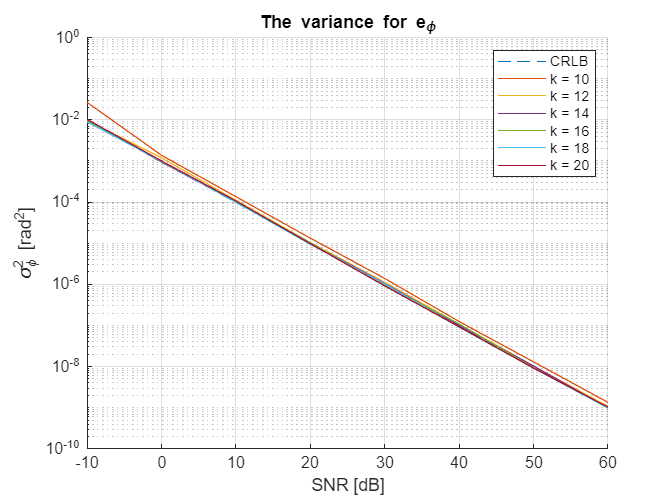

% --- PLOTTING ---
figure; grid on; hold on;
plot(SNR, CRLB_phi, '--', 'DisplayName', 'CRLB');
for i = 1:length(M)
    plot(SNR, var_error_phase(:, i), 'DisplayName', sprintf('k = %.0f', log2(M(i))));
end
set(gca, 'YScale', 'log');
title('The variance for e_{\phi}');
xlabel('SNR [dB]'); ylabel('\sigma^2_{\phi} [rad^2]');
legend; hold off;

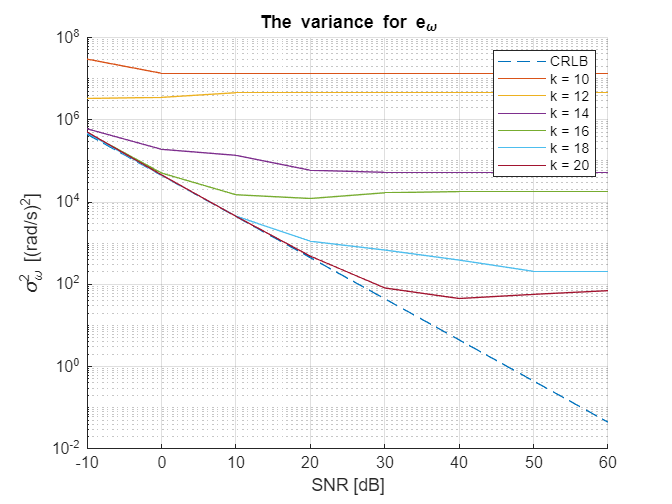


figure; grid on; hold on;
plot(SNR, CRLB_w, '--', 'DisplayName', 'CRLB');
for i = 1:length(M)
    plot(SNR, var_error_freq(:, i), 'DisplayName', sprintf('k = %.0f', log2(M(i))));
end
set(gca, 'YScale', 'log');
title('The variance for e_{\omega}');
xlabel('SNR [dB]'); ylabel('\sigma^2_{\omega} [(rad/s)^2]');
legend; hold off;

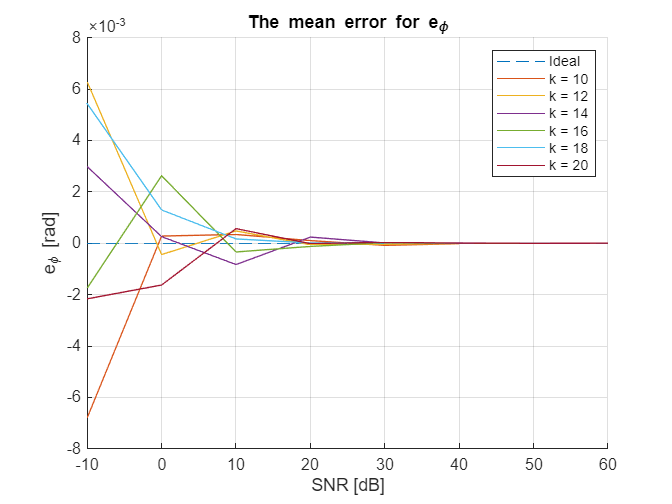


figure; grid on; hold on;
plot(SNR, zeros(size(SNR)), '--', 'DisplayName', 'Ideal');
for i = 1:length(M)
    plot(SNR, error_phase_mean (:, i), 'DisplayName', sprintf('k = %.0f', log2(M(i))));
end
title('The mean error for e_{\phi}');
xlabel('SNR [dB]'); ylabel('e_{\phi} [rad]');
legend; hold off;

legend(["Perfect estimator", "k = 10", "k = 12", "k = 14", "k = 16", "k = 18", "k = 20"])

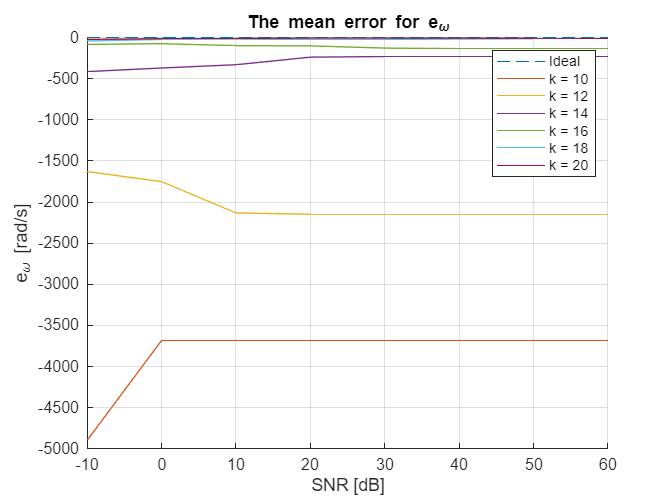


figure; grid on; hold on;
plot(SNR, zeros(size(SNR)), '--', 'DisplayName', 'Ideal');
for i = 1:length(M)
    plot(SNR, error_freq_mean(:, i), 'DisplayName', sprintf('k = %.0f', log2(M(i))));
end
title('The mean error for e_{\omega}');
xlabel('SNR [dB]'); ylabel('e_{\omega} [rad/s]');
legend; hold off;

legend(["Perfect estimator", "k = 10", "k = 12", "k = 14", "k = 16", "k = 18", "k = 20"])

%%Task 1b

%Setting up the parameters for the simulations
A = 1;
Fs = 10^6;
T = 1/Fs;
f0 = 10^5;
w0 = 2*pi*f0;
phase0 = pi/8;
N = 513;
simulations = 500;

%Setting up P and Q for the CRLB
P = N * (N - 1) / 2;
Q = N * (N - 1) * (2 * N - 1) / 6;

%initial sample chosen to get a diagonal matrix for the covariance matrix
%to analyse frequency estimation and phase estimation independently.
n_0 = -P/N;

M = 2^10; %Lenght of the FFT
n = n_0:(n_0 + N - 1); % List of samples
SNR = -10:10:60; % Signal-to-noise ratio in dB (given)
variances = (A^2) ./(2*(10.^(SNR/10))); % Variance of the noise for each given SNR

%initializing error matrices:
error_freq = zeros(length(SNR), simulations);
error_phase = zeros(length(SNR), simulations);

%Running simulations to find the errors
options = optimset("MaxFunEvals", 10000, "MaxIter",1000, "Display", "notify", "FunValCheck", "on", "TolFun", 1e-4, "TolX", 1e-4);

for i = 1:length(variances)
    for j=1:simulations
        % Generates signal with noise
            [signal_with_noise, ~] = generate_noisy_signal(variances(i), A, phase0, n, T, w0);
            
            %FFT
            signal_with_noise_fft = fft(signal_with_noise, M);
            
            %Find MLE-estimates, will be a good starting point to minimize
            %the error
            [w_hat, phi_hat] = Find_MLE(signal_with_noise, signal_with_noise_fft, M, N, T, n_0);

            %Creating a bad estimate, bad starting point
            [w_hat_bad, phi_hat_bad] = Find_badE(signal_with_noise, signal_with_noise_fft, M, N, T, n_0);

            Nelder_mean_start0 = [w_hat, phi_hat];
            Nelder_mean_start1 = [w_hat_bad, phi_hat_bad];

            [optimal_arg,fval,exitflag,output] = fminsearch( @(x) cost_function(x,signal_with_noise, A, n, T, M), Nelder_mean_start0,options);

            e_w = w0 - optimal_arg(1);
            e_phi = phase0 - optimal_arg(2);

            error_freq(i,j) = e_w;
            error_phase(i,j) = e_phi;
    end
end

%Finding the mean of the estimation errors 
error_freq_mean = zeros(length(variances),1);
error_phase_mean = zeros(length(variances),1);

for i = 1:length(variances)
        error_freq_mean(i) = calculate_mean(error_freq(i,:));
        error_phase_mean(i) = calculate_mean(error_phase(i,:));
end

%Finding variance of estimation errors
var_error_freq = zeros(length(variances),1);
var_error_phase = zeros(length(variances),1);

for i = 1:length(variances)
        var_error_freq(i) = calculate_variance(error_freq(i,:));
        var_error_phase(i) = calculate_variance(error_phase(i,:));
end

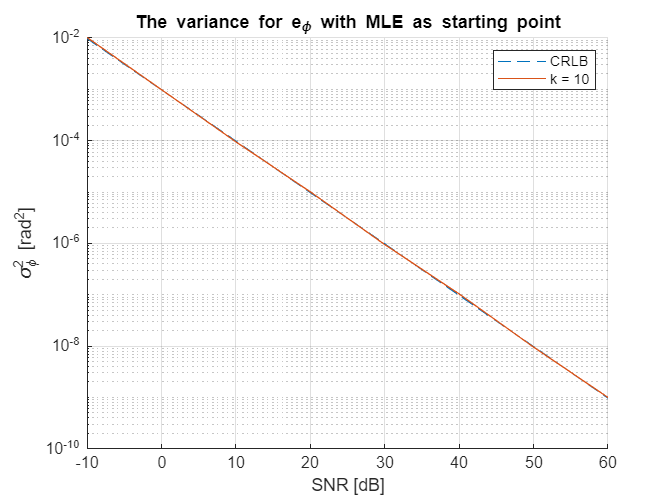

% --- PLOTTING ---
figure; grid on; hold on;
plot(SNR, CRLB_phi, '--', 'DisplayName', 'CRLB');
plot(SNR, var_error_phase, 'DisplayName', sprintf('k = %.0f', log2(M)));
set(gca, 'YScale', 'log');
title('The variance for e_{\phi} with MLE as starting point');
xlabel('SNR [dB]'); ylabel('\sigma^2_{\phi} [rad^2]');
legend; hold off;

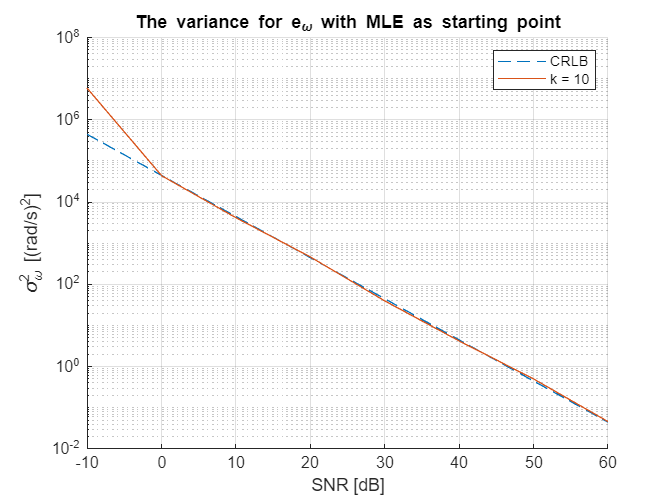


figure; grid on; hold on;
plot(SNR, CRLB_w, '--', 'DisplayName', 'CRLB');
plot(SNR, var_error_freq, 'DisplayName', sprintf('k = %.0f', log2(M)));
set(gca, 'YScale', 'log');
title('The variance for e_{\omega} with MLE as starting point');
xlabel('SNR [dB]'); ylabel('\sigma^2_{\omega} [(rad/s)^2]');
legend; hold off;

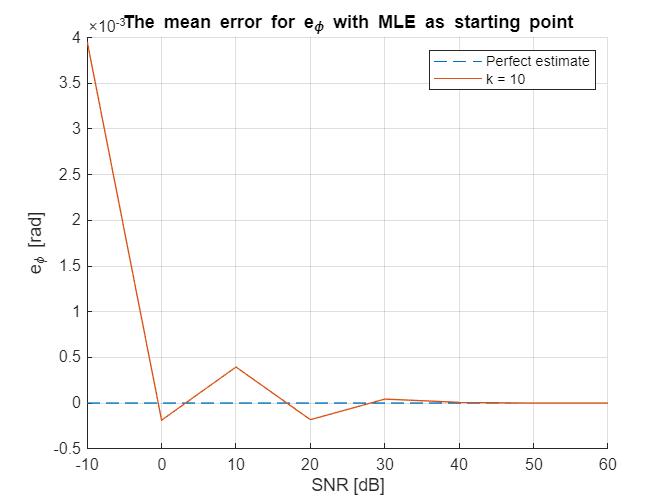


figure; grid on; hold on;
plot(SNR, zeros(size(SNR)), '--', 'DisplayName', 'Perfect estimate');
plot(SNR, error_phase_mean, 'DisplayName', sprintf('k = %.0f', log2(M)));
title('The mean error for e_{\phi} with MLE as starting point');
xlabel('SNR [dB]'); ylabel('e_{\phi} [rad]');
legend; hold off;

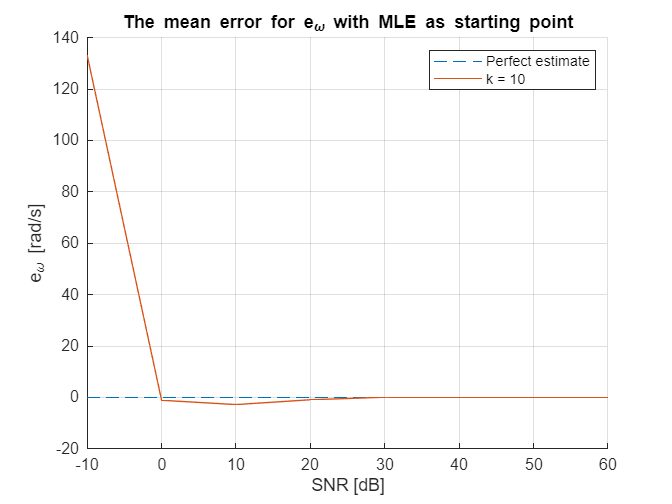


figure; grid on; hold on;
plot(SNR, zeros(size(SNR)), '--', 'DisplayName', 'Perfect estimate');
plot(SNR, error_freq_mean, 'DisplayName', sprintf('k = %.0f', log2(M)));
title('The mean error for e_{\omega} with MLE as starting point');
xlabel('SNR [dB]'); ylabel('e_{\omega} [rad/s]');
legend; hold off